% Ashwin Foucault Q5 %
%--------------------%
% N.B. Signal Processing Toolbox is required!

clear

format long

tic
L = 67;
Omega = 2*pi/86164; 
sigma = pi/180*(0); 
m = 28; 
R_E = 6371000;
% gamma = 0; 
g = 9.81;

K = Omega*cos(sigma);


% Defines RHS of coupled ODEs
function state = fsolver(t,u)

L = 67;
Omega = 2*pi/86164; 
sigma = pi/180*(0); 
m = 28; 
R_E = 6371000;
g = 9.81;
R = 8.5*1e-2; 
mu = 1.81*1e-5; 

%gamma = 0.00000; 
gamma = 6*pi*mu*R;

K = Omega*cos(sigma);

state = zeros(4,1); 

state(1:2) = u(3:4); 
z = -sqrt(L^2-(u(1))^2-(u(2))^2); 
zdot = -(u(1)*u(3) + u(2)*u(4))/(z);

Eqx = 2*K*u(4) + ((Omega)^2)*R_E*cos(sigma)*sin(sigma) - gamma/m*u(3); 
Eqy = -2*Omega*sin(sigma)*zdot - 2*K*u(3) - gamma/m*u(4); 
Eqz = 2*Omega*sin(sigma)*u(4) - g - gamma/m*zdot; 

xddot = 1/(L^2 + (u(1))^2 + (u(2))^2)*(Eqx*(L^2 + (u(2))^2 - (u(1))^2) - 2*Eqy*u(1)*u(2) - Eqz*u(1)*z + (u(1)/z^2)*((u(3)*u(2) - u(4)*u(1))^2 - L^2*((u(3))^2 + (u(4))^2))); 
yddot = 1/(L^2 + (u(1))^2 + (u(2))^2)*(Eqy*(L^2 - (u(2))^2 + (u(1))^2) - 2*Eqx*u(1)*u(2) - Eqz*u(2)*z + (u(2)/z^2)*((u(3)*u(2) - u(4)*u(1))^2 - L^2*((u(3))^2 + (u(4))^2))); 

state(3:4) = [xddot; yddot]; 

end

% Defines initial conditions [x0; y0; vx0; vy0]
state_init = [3;0;0;0]; 

% Defines timespan(s)
N = 200000

N =       200000


tspan = linspace(0,10*86164,N);
tspan_other = linspace(0,2*pi/K,N);

% Solves ODEs 
opts = odeset('RelTol',1e-10,'AbsTol',1e-10);
[t, state] = ode45(@fsolver, tspan, state_init, opts);

% Defines x, y, z positions and horizontal radial distance 
xs = state(:,1);
ys = state(:,2);
zs = -sqrt(L^2-(xs).^2-(ys).^2);
rs = sqrt(xs.^2+ys.^2);

% Defines x, y, z velocities and squared magnitude of velocity
xdots = state(:,3);
ydots = state(:,4);
zdots = (xs.*xdots + ys.*ydots)./(-zs);
vels_sq = xdots.^2 + ydots.^2 + zdots.^2;

% Defines kinetic, gravitational potential and total energies 
kins = 1/2*m*vels_sq;
pots = m*g*(zs+L);
energies = kins + pots;

% Creates upper and lower envelopes for the (generally) rapidly oscillating
% xs and ys 
[E_xs_upper,E_xs_lower] = envelope(xs,10,'peak');
[E_ys_upper,E_ys_lower] = envelope(ys,10,'peak'); 

[E_rs_upper,E_rs_lower] = envelope(rs,100,'peak');
logE_rs = log(E_rs_upper);
%[E_E_rs_upper,E_E_rs_lower] = envelope(E_rs_upper,10000,'peak');


E_xs = zeros(2,N);
E_ys = zeros(2,N);
E_xs(1,:) = E_xs_upper;
E_xs(2,:) = E_xs_lower;
E_ys(1,:) = E_ys_upper;
E_ys(2,:) = E_ys_lower;

% Sets minimum peak prominence 
minPP = norm(state_init)/20;

% Finds "zeros" of x and y envelopes by finding peaks of lower envelopes
[xpeaks,xlocs] = findpeaks(E_xs_lower,MinPeakProminence = minPP)

xpeaks =   -2.668777593843535
  -2.042476834305191
  -2.160947855478885
  -2.046770152774935
  -2.150234534123043
  -2.049031098405286
  -2.985143256537298
  -2.137146163838299
  -2.049241276725683
  -2.974357018175060
  -2.121711739923425
  -2.047383806765708
  -2.960439228600991
  -2.103963500118954
  -2.043443371239769


xlocs =     11
    52
   114
   155
   217
   258
   289
   320
   361
   392
   423
   464
   495
   526
   567


[ypeaks,ylocs] = findpeaks(E_ys_lower,MinPeakProminence = minPP)

ypeaks =   -0.323493203291907
  -0.351799212892213
  -0.392768307560123
  -0.415771468735789
  -0.462084465262037
  -0.478761405252439
  -0.531376807743050
  -0.540690566370255
  -0.600579677678912
  -0.603092035904003
  -0.669626673542727
  -0.668192291168181
  -0.738450696592916
  -0.733108616360220
  -0.802526559356246


ylocs =          485
         547
         588
         650
         691
         753
         794
         856
         897
         958
        1000
        1061
        1103
        1164
        1226


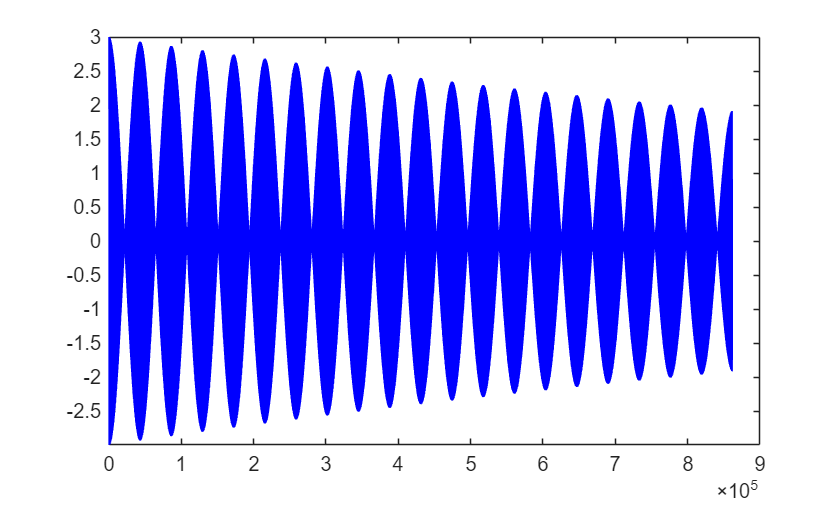


% Initialises vectors for the locus of one extremum of oscillation in x and
% y directions 
x_outline = zeros(1,N); 
y_outline = zeros(1,N); 

% Defines these vectors in terms of parts of either the upper or lower 
% envelopes, depending on which index has been reached between peaks 
% N.B. This assumes that the initial displacement is positive (and small)! 
if isempty(xpeaks)
    x_outline = E_xs_upper';
elseif length(xpeaks) == 1
    x_outline(1:xlocs(1)) = E_xs_upper(1:xlocs(1));
    x_outline(xlocs(1)+1:N) = E_xs_lower(xlocs(1)+1:N);
else
    x_outline(1:xlocs(1)) = E_xs_upper(1:xlocs(1));
    for k = 1:length(xpeaks)-1
        x_outline(xlocs(k)+1:xlocs(k+1)) = E_xs((3/2+1/2*(-1)^(k+1)), xlocs(k)+1:xlocs(k+1));
    end
    x_outline(xlocs(length(xpeaks))+1:N) = E_xs((3/2+1/2*(-1)^(length(xpeaks)+1)), xlocs(length(xpeaks))+1:N);
end

% Changes which part of the y-envelope is used depending on the hemisphere 
if cos(sigma) >= 0
    if isempty(ypeaks)
        y_outline = E_ys_lower';
    elseif length(ypeaks) == 1
        y_outline(1:ylocs(1)) = E_ys_lower(1:ylocs(1));
        y_outline(ylocs(1)+1:N) = -E_ys_lower(ylocs(1)+1:N);
    else
        y_outline(1:ylocs(1)) = E_ys_lower(1:ylocs(1));
        for k = 1:length(ypeaks)-1
            y_outline(ylocs(k)+1:ylocs(k+1)) = E_ys((3/2+1/2*(-1)^(k)), ylocs(k)+1:ylocs(k+1));
        end
        y_outline(ylocs(length(ypeaks))+1:N) = E_ys((3/2+1/2*(-1)^(length(ypeaks))), ylocs(length(ypeaks))+1:N);
    end
else
    if isempty(ypeaks)
        y_outline = E_ys_upper';
    elseif length(ypeaks) == 1
        y_outline(1:ylocs(1)) = E_ys_upper(1:ylocs(1));
        y_outline(ylocs(1)+1:N) = -E_ys_upper(ylocs(1)+1:N);
    else
        y_outline(1:ylocs(1)) = E_ys_upper(1:ylocs(1));
        for k = 1:length(ypeaks)-1
            y_outline(ylocs(k)+1:ylocs(k+1)) = E_ys((3/2+1/2*(-1)^(k+1)), ylocs(k)+1:ylocs(k+1));
        end
        y_outline(ylocs(length(ypeaks))+1:N) = E_ys((3/2+1/2*(-1)^(length(ypeaks)+1)), ylocs(length(ypeaks))+1:N);
    end
end

% Defines angle turned through by extremum and theoretical angle (for small
% displacements) obtained analytically 
if cos(sigma) >= 0
    angle = (mod(atan2(-y_outline, x_outline),2*pi) - mod(atan2(-ys(1), xs(1)),2*pi));
else
    angle = (mod(atan2(y_outline, x_outline),2*pi) - mod(atan2(ys(1), xs(1)),2*pi));
end
angle_theos = K*tspan;
angle_diff = -(angle - angle_theos);
%x_outline
%y_outline

k = sqrt(K^2 + g/L);
x_preds = state_init(1).*(cos(K.*tspan));
y_preds = state_init(1).*(-sin(K.*tspan));

clf

plot(tspan, xs,"b")
ylim([min(xs),max(xs)])

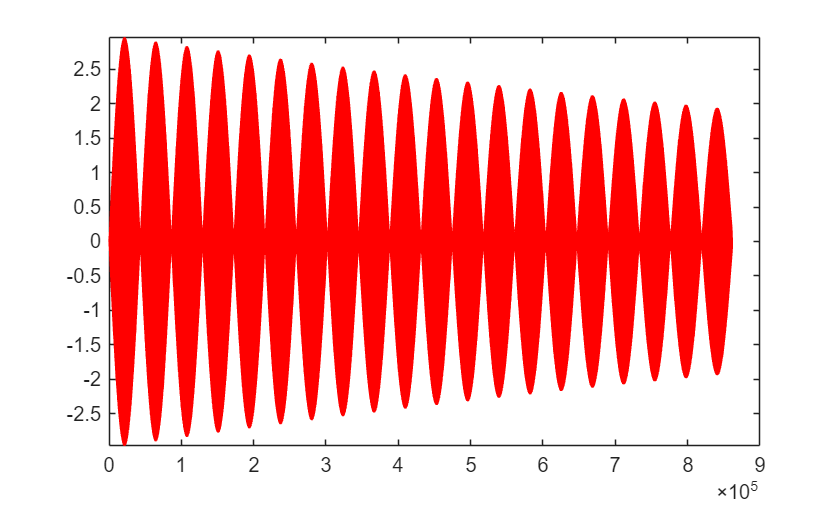

plot(tspan, ys,"r")
ylim([min(ys),max(ys)])

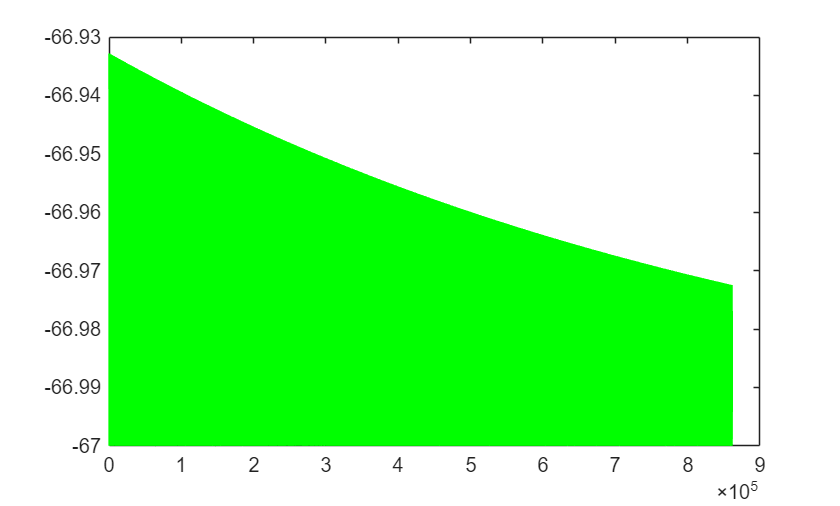

plot(tspan, zs,"g")

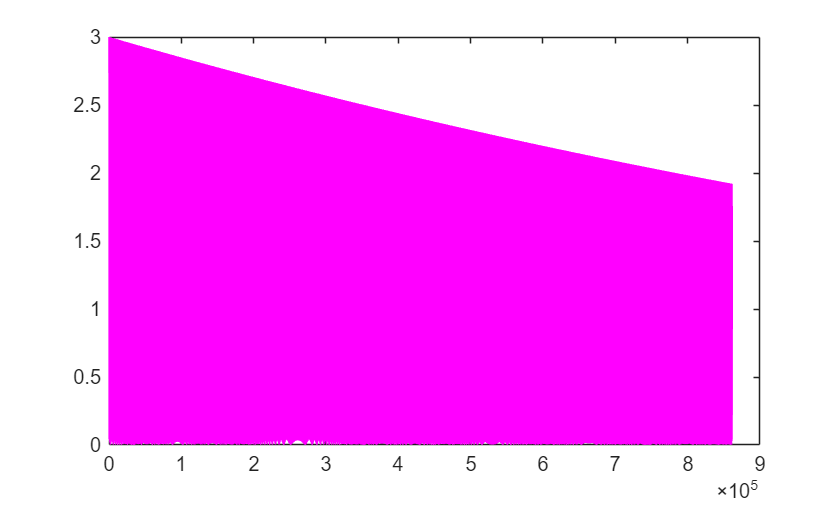

plot(tspan, rs,"m")

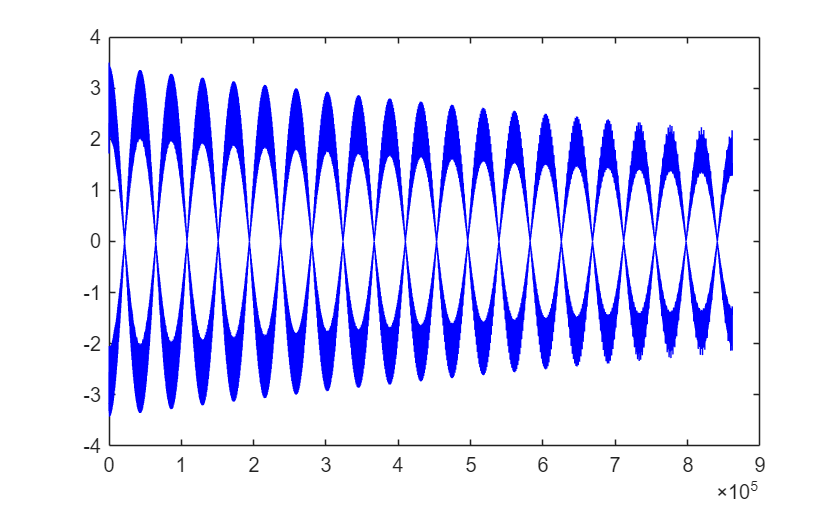



plot(tspan, E_xs_upper, "b", tspan, E_xs_lower, "b")

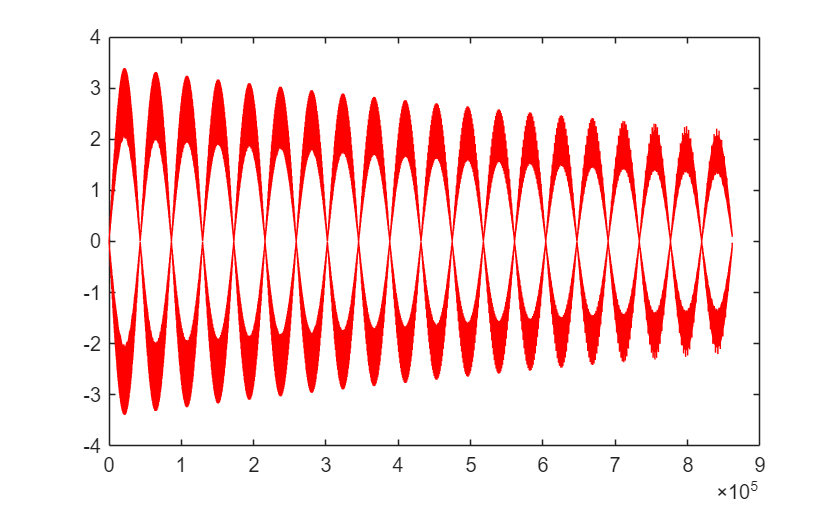

plot(tspan, E_ys_upper, "r", tspan, E_ys_lower, "r")

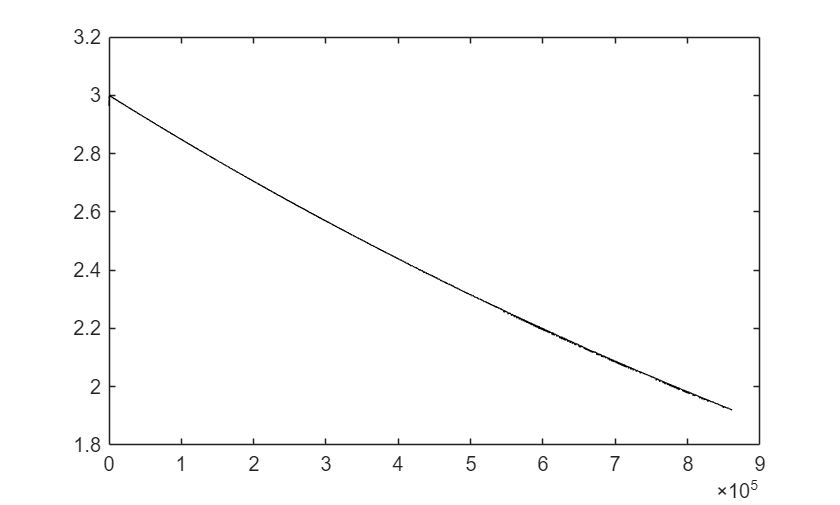


%plot(tspan, E_E_rs_upper, "m")
plot(tspan, E_rs_upper, "k")

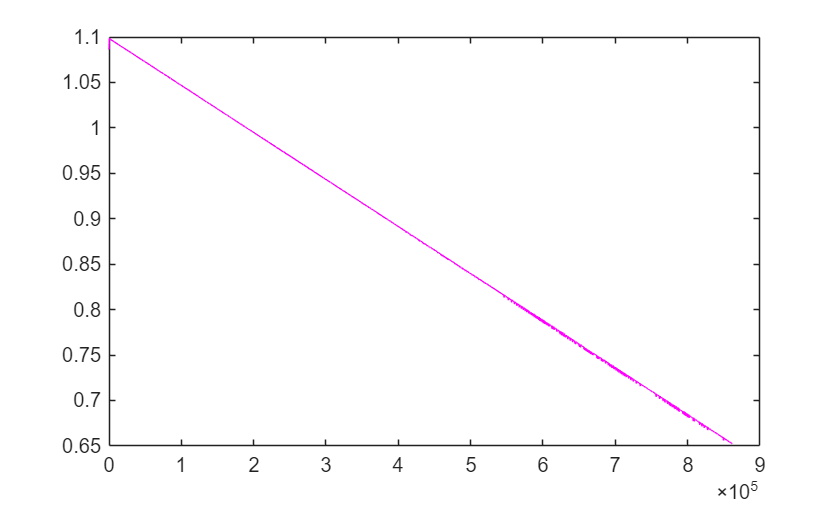

plot(tspan, logE_rs, "m")

%plot(tspan, log(E_E_rs_upper),"k")

%ylim([0,1.1*max(E_rs_upper)])
logrslope = (logE_rs(end-24)-logE_rs(25))/(tspan(end-4)-tspan(5))

logrslope =     -5.090236853904787e-07


logrintercept = logE_rs(5) 

logrintercept =    1.087373989965586


A = exp(logrintercept) 

A =    2.966473845223534


k = -logrslope 

k =      5.090236853904787e-07


halflife = log(2)/k 

halflife =      1.361718914962126e+06


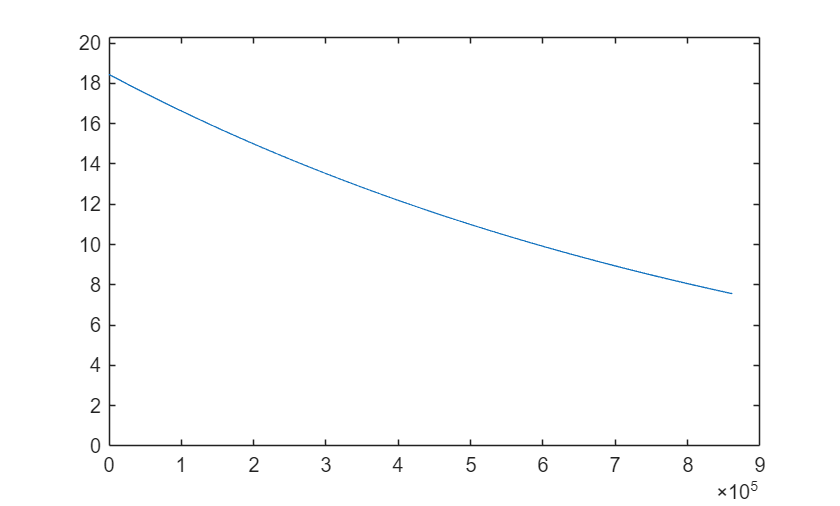


%plot(tspan,kins,tspan,pots)
plot(tspan,energies)
ylim([0,1.1*max(energies)])

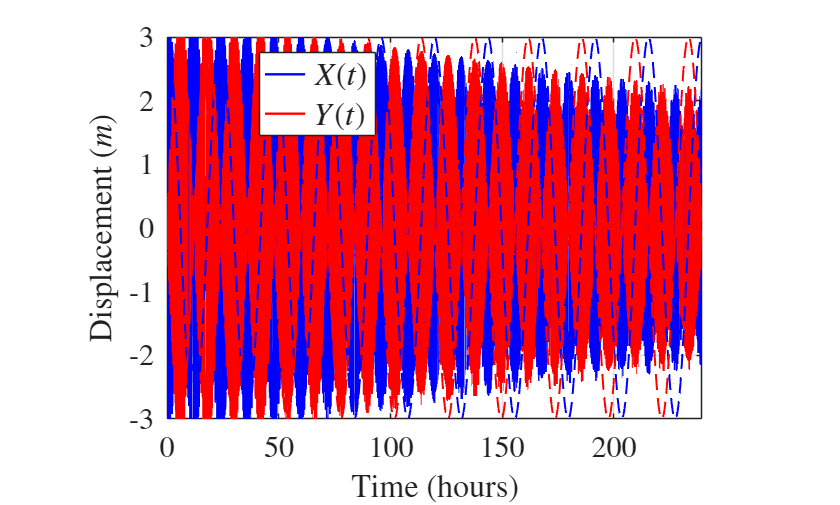


plot(tspan/3600, x_outline,"b", DisplayName = "$X(t)$", LineWidth = 1.2)
hold on 
plot(tspan/3600, y_outline,"r", DisplayName = "$Y(t)$", LineWidth = 1.2)
if state_init(2) == 0
    plot(tspan/3600, x_preds,"b--", DisplayName = "$X_{pred}(t)}$", LineWidth = 1.0)
    plot(tspan/3600, y_preds,"r--", DisplayName = "$Y_{pred}(t)$", LineWidth = 1.0)
end
xlim([tspan(1)/3600,tspan(end)/3600])
ylim([-norm(state_init),norm(state_init)])
ax1 = gca;
ax1.TickLabelInterpreter = 'latex';
ax1.XAxis.FontSize = 15;
ax1.YAxis.FontSize = 15;
xlabel("Time (hours)", Interpreter = 'latex', FontSize = 16)
ylabel("Displacement ($m$)", Interpreter = 'latex', FontSize = 16)
lgd1 = legend("$X(t)$", "$Y(t)$", Position = [0.3084 0.7302 0.1391, 0.1651], Interpreter = 'latex', FontSize = 16);
lgd1.IconColumnWidth = 20;
%lgd2 = legend("$X_{pred}(t)$", "$Y_{pred}(t)$", location = "southeast", Interpreter = 'latex')
hold off
grid on
pbaspect([1.4,1,1])

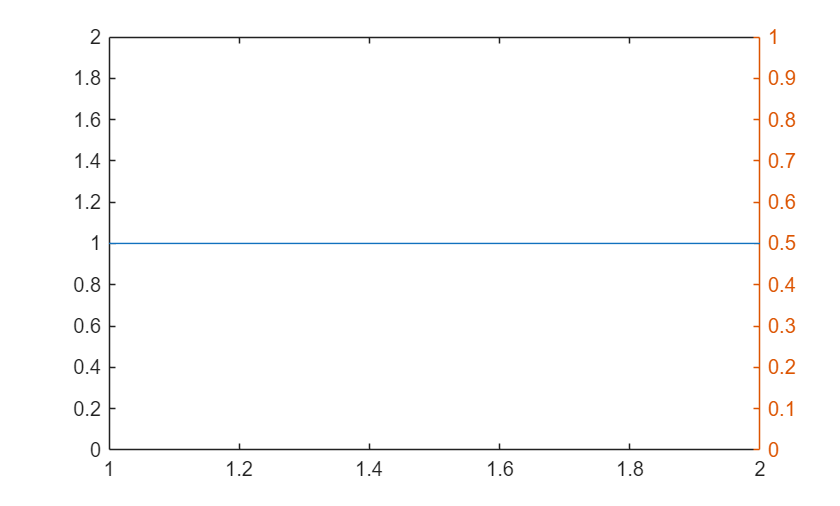


% Creates a buffer plot (as the double y-axis leaks into previous plot)
plot([1,1])
cutoff = 153822;

yyaxis left
p21 = plot(tspan(1:cutoff)/3600, 180/pi*angle_theos(1:cutoff), "-.", DisplayName = "Predicted", LineWidth = 1.2);

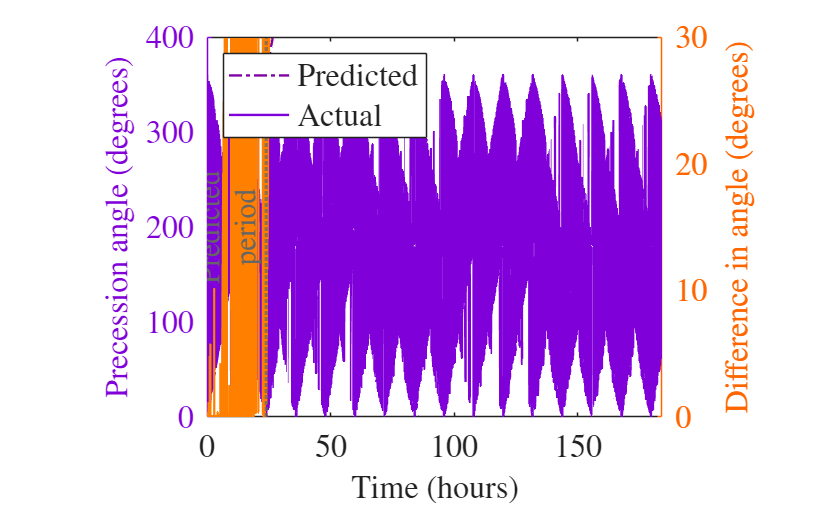

p21.Color = [0.5 0 0.6500];
hold on
p22 = plot(tspan(1:cutoff)/3600, 180/pi*angle(1:cutoff), "b-", DisplayName = "Actual", LineWidth = 1.2);
p22.Color = [0.5 0 0.8500];
ax2 = gca;
ax2.TickLabelInterpreter = 'latex';
ax2.XAxis.FontSize = 16;
ax2.YAxis(1).FontSize = 16;
ax2.YAxis(1).Color = [0.5 0 0.8500];
xlabel("Time (hours)", Interpreter = 'latex', FontSize = 16)
ylabel("Precession angle (degrees)", Interpreter = 'latex', FontSize = 16)
xlim([tspan(1)/3600,tspan(cutoff)/3600])
ylim([0,400])
lgd3 = legend(location = 'northwest', Interpreter = 'latex', FontSize = 16);

lbl = {'Predicted','period'};
greycolor = [0.4 0.4 0.4];
xl = xline(2*pi/K/3600, ":", {'\text{Predicted}','\text{period}'}, LineWidth = 1.6, LabelVerticalAlignment = "middle", LabelHorizontalAlignment = 'left', HandleVisibility = 'off', Interpreter = 'latex', FontSize = 15);
xl.Color = greycolor; 

yyaxis right
ax2.YAxis(2).Color = [1 0.4 0];
p = plot(tspan(1:cutoff)/3600, 180/pi*angle_diff(1:cutoff), DisplayName = "Difference", HandleVisibility = 'off', LineWidth = 1.1);
p.Color = [1 0.5 0];
ax2.YAxis(2).FontSize = 16;
ylabel("Difference in angle (degrees)", Interpreter = 'latex', FontSize = 16)
ylim([0,30])
pbaspect([1.2,1,1])


%(tspan(xlocs(3))-tspan(xlocs(1)))/3600  
(Omega)^2*R_E*cos(sigma)*sin(sigma)

ans =      0



E_xs_upper

E_xs_upper =    1.721550396868659
   2.070549263840012
   2.375386135288348
   2.638307582470599
   2.861560176643698
   3.047390489064576
   3.198045090990164
   3.315770553677396
   3.402813448383204
   3.461420346364518
   3.493837818878272
   3.502312437181397
   3.489090772530825
   3.456419396183489
   3.406544879396319


E_xs_lower

E_xs_lower =   -3.160057235801081
  -3.055505353549966
  -2.965183574486943
  -2.888374269754423
  -2.824359810494819
  -2.772422567850544
  -2.731844912964009
  -2.701909216977629
  -2.681897851033815
  -2.671093186274979
  -2.668777593843535
  -2.674233444881895
  -2.686743110532472
  -2.705588961937677
  -2.730053370239924



toc

Elapsed time is 352.019204 seconds.
